
clear all, close all, clc

m = 1;
M = 5;
L = 2;
g = -10;
d = 1;

s = 1; % pendulum up (s=1)

A = [0 1 0 0;
    0 -d/M -m*g/M 0;
    0 0 0 1;
    0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];



B = [0; 1/M; 0; s*1/(M*L)];
eig(A)

ans =          0
   -2.4674
   -0.1665
    2.4339



Q = [1 0 0 0;
    0 1 0 0;
    0 0 10 0;
    0 0 0 100];
R = .0001;

%%
det(ctrb(A,B))

ans = 0.0100

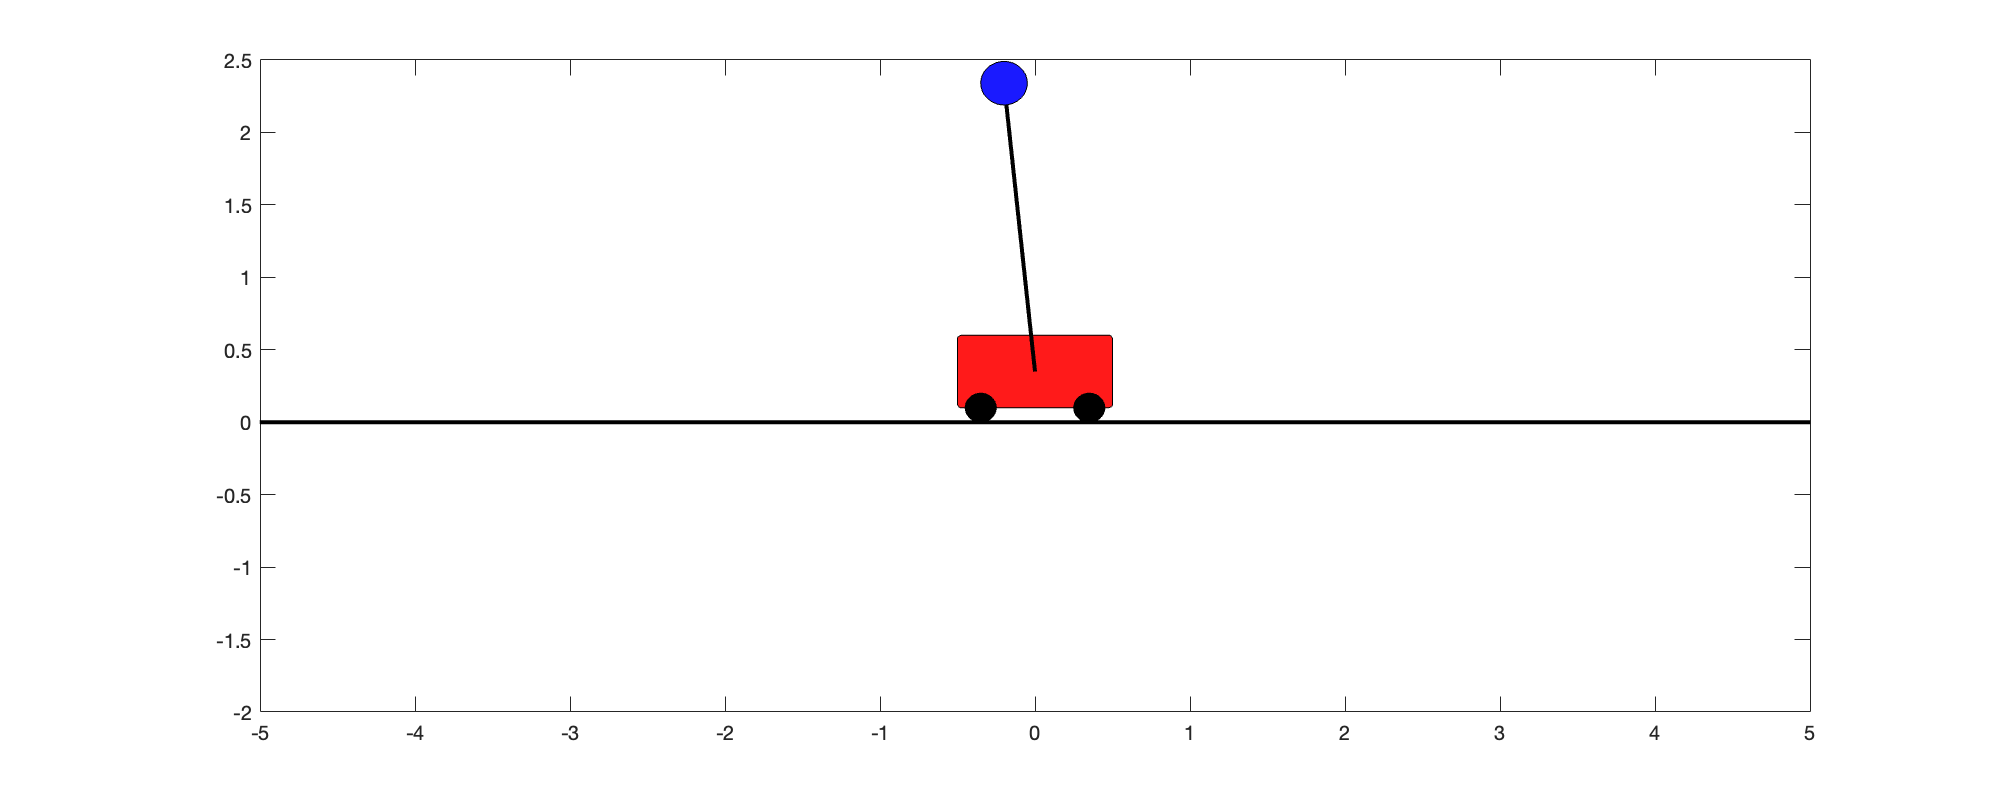

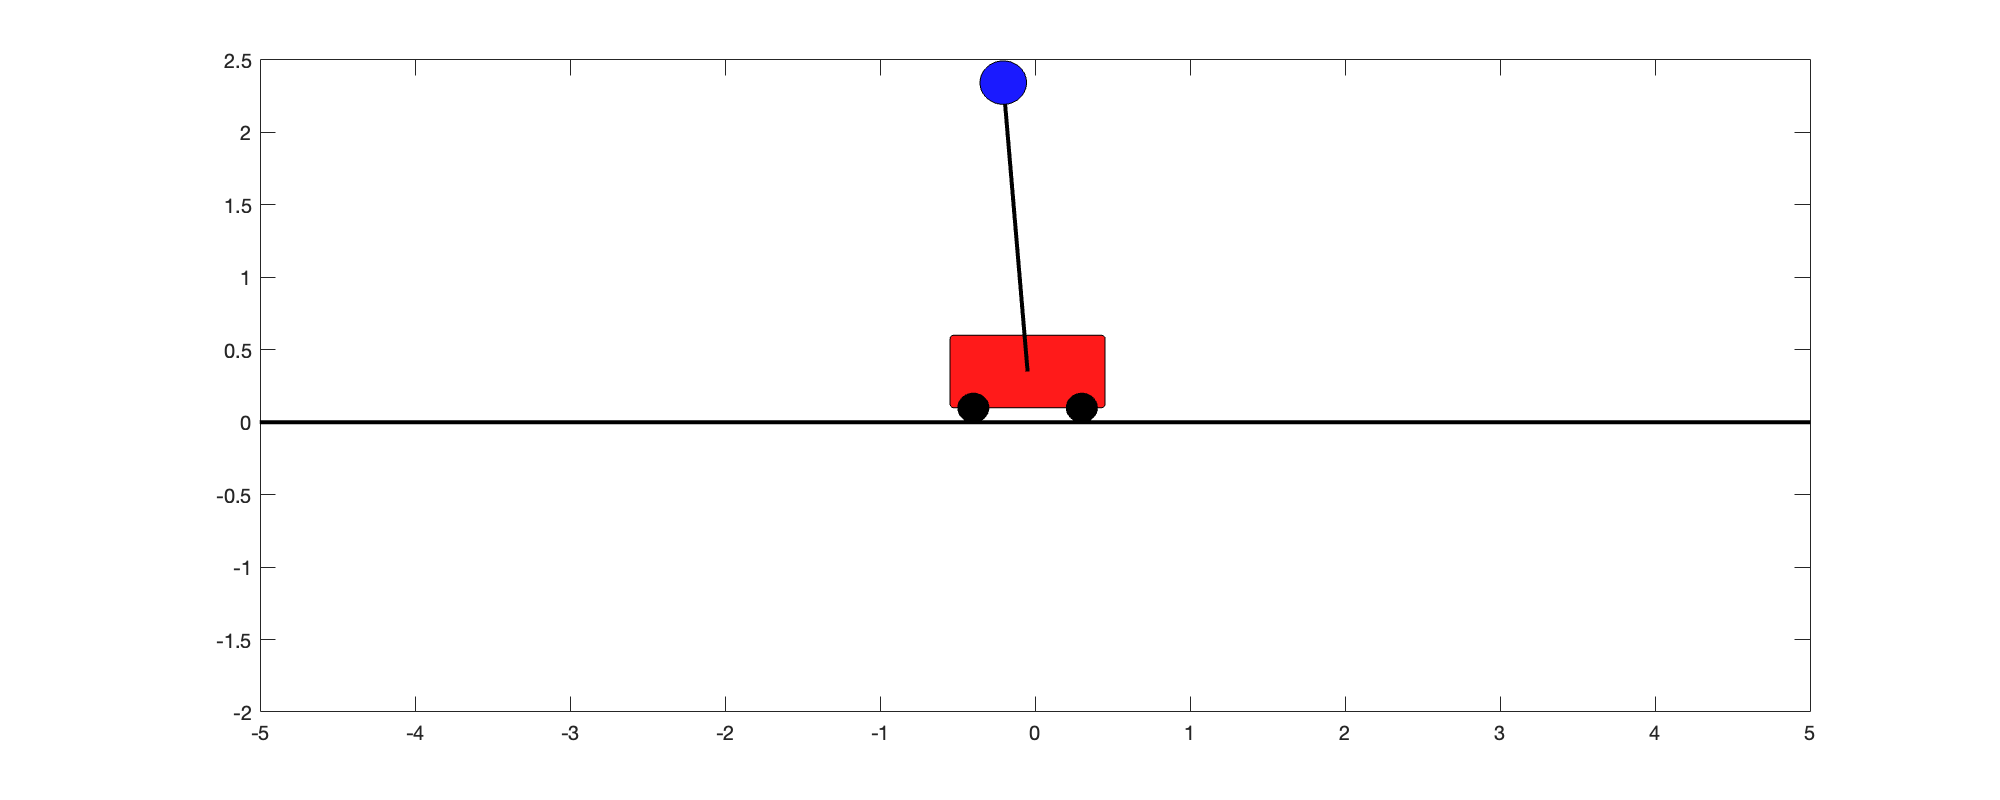

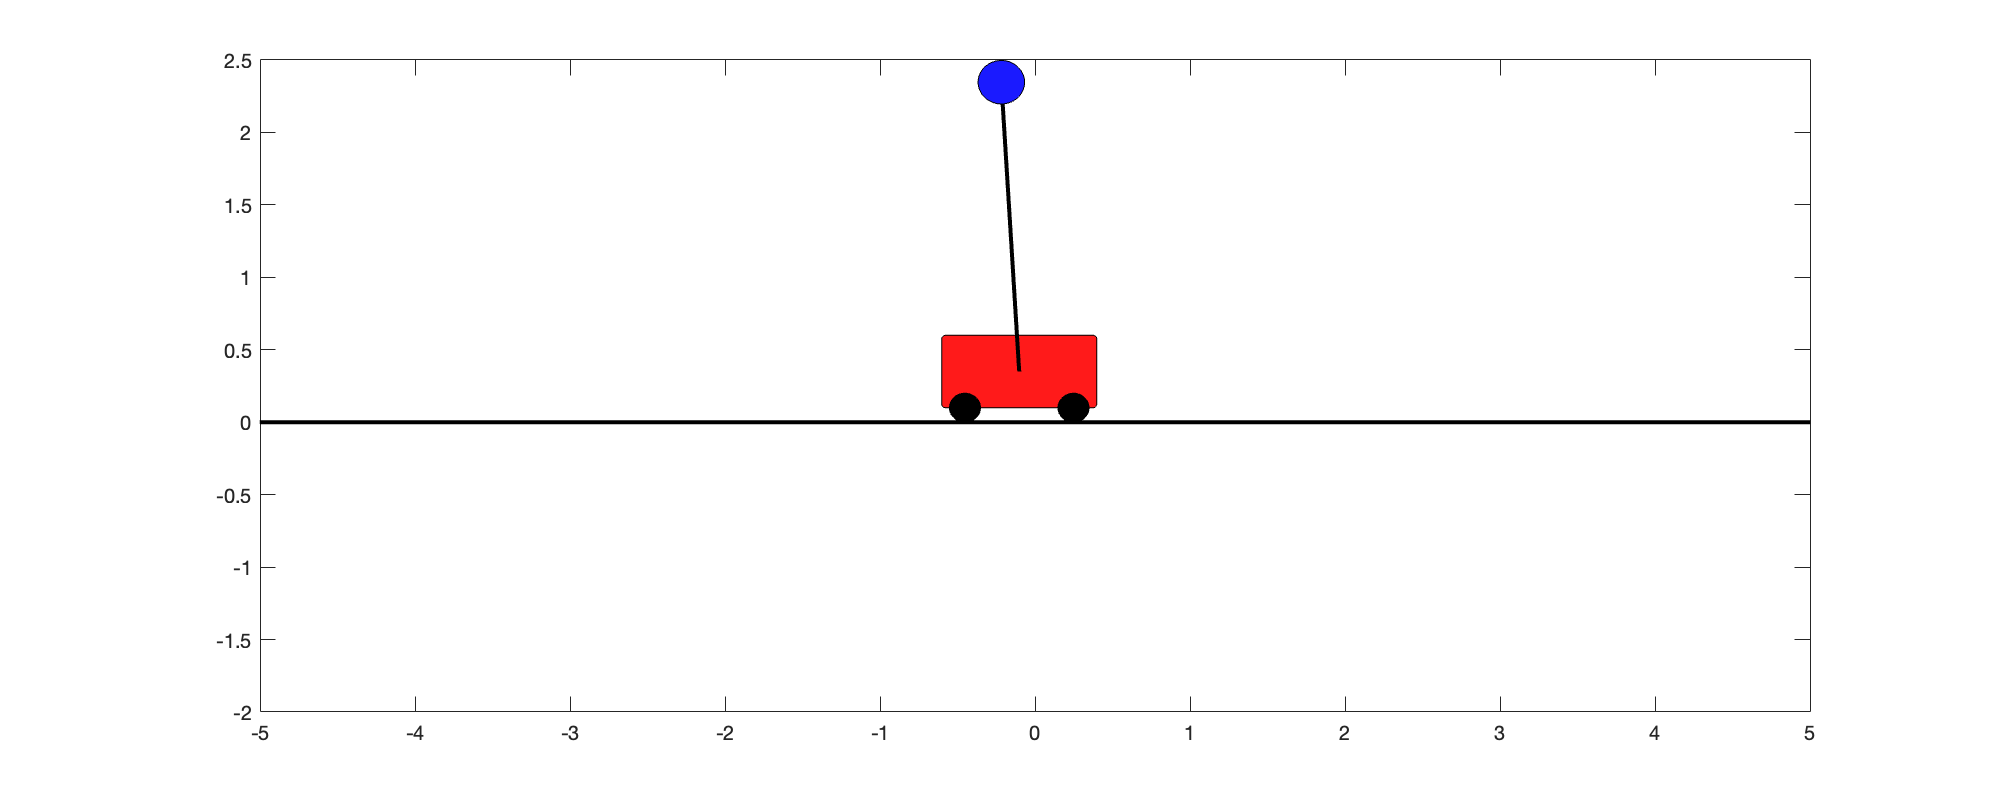

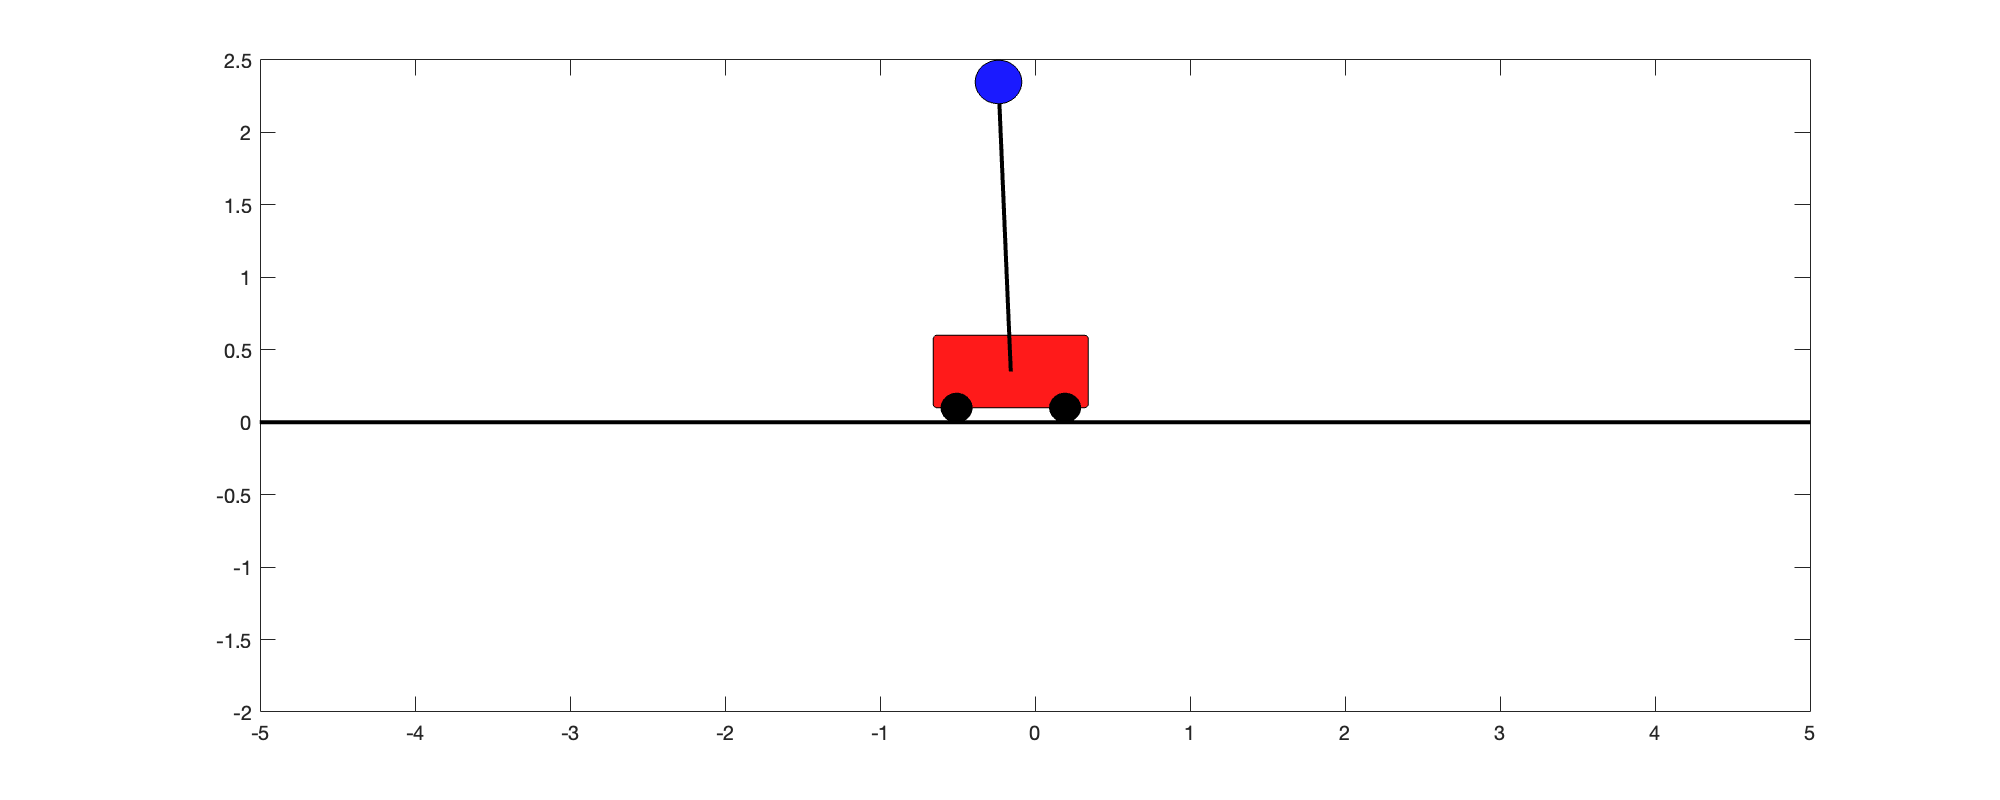

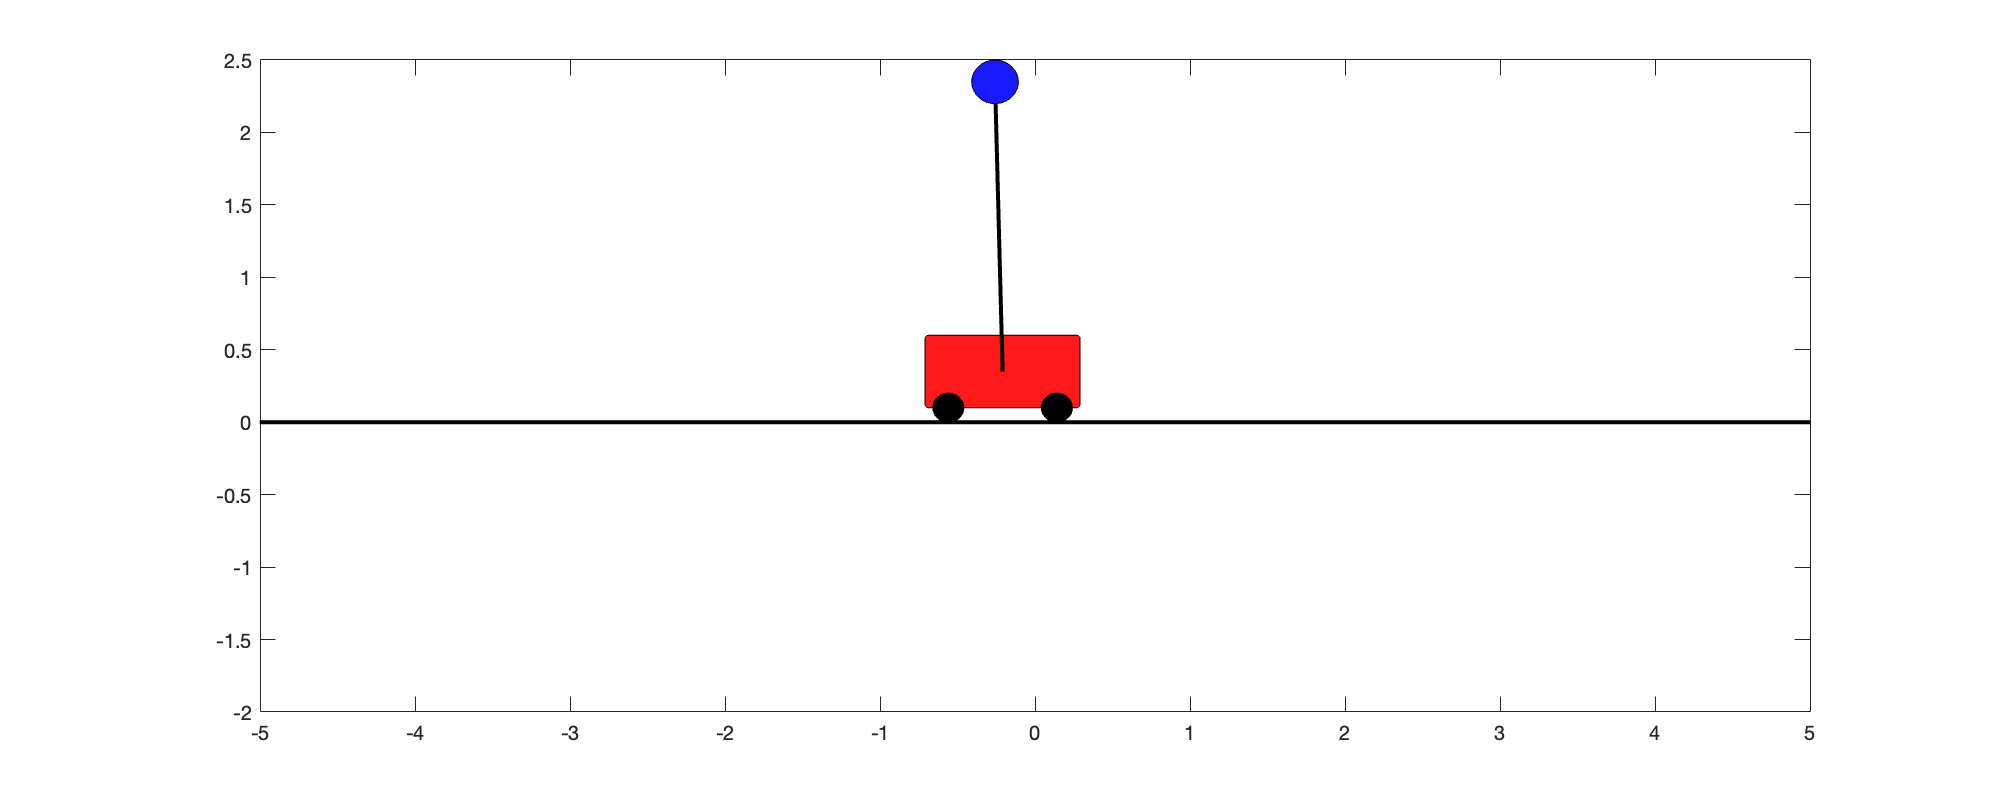

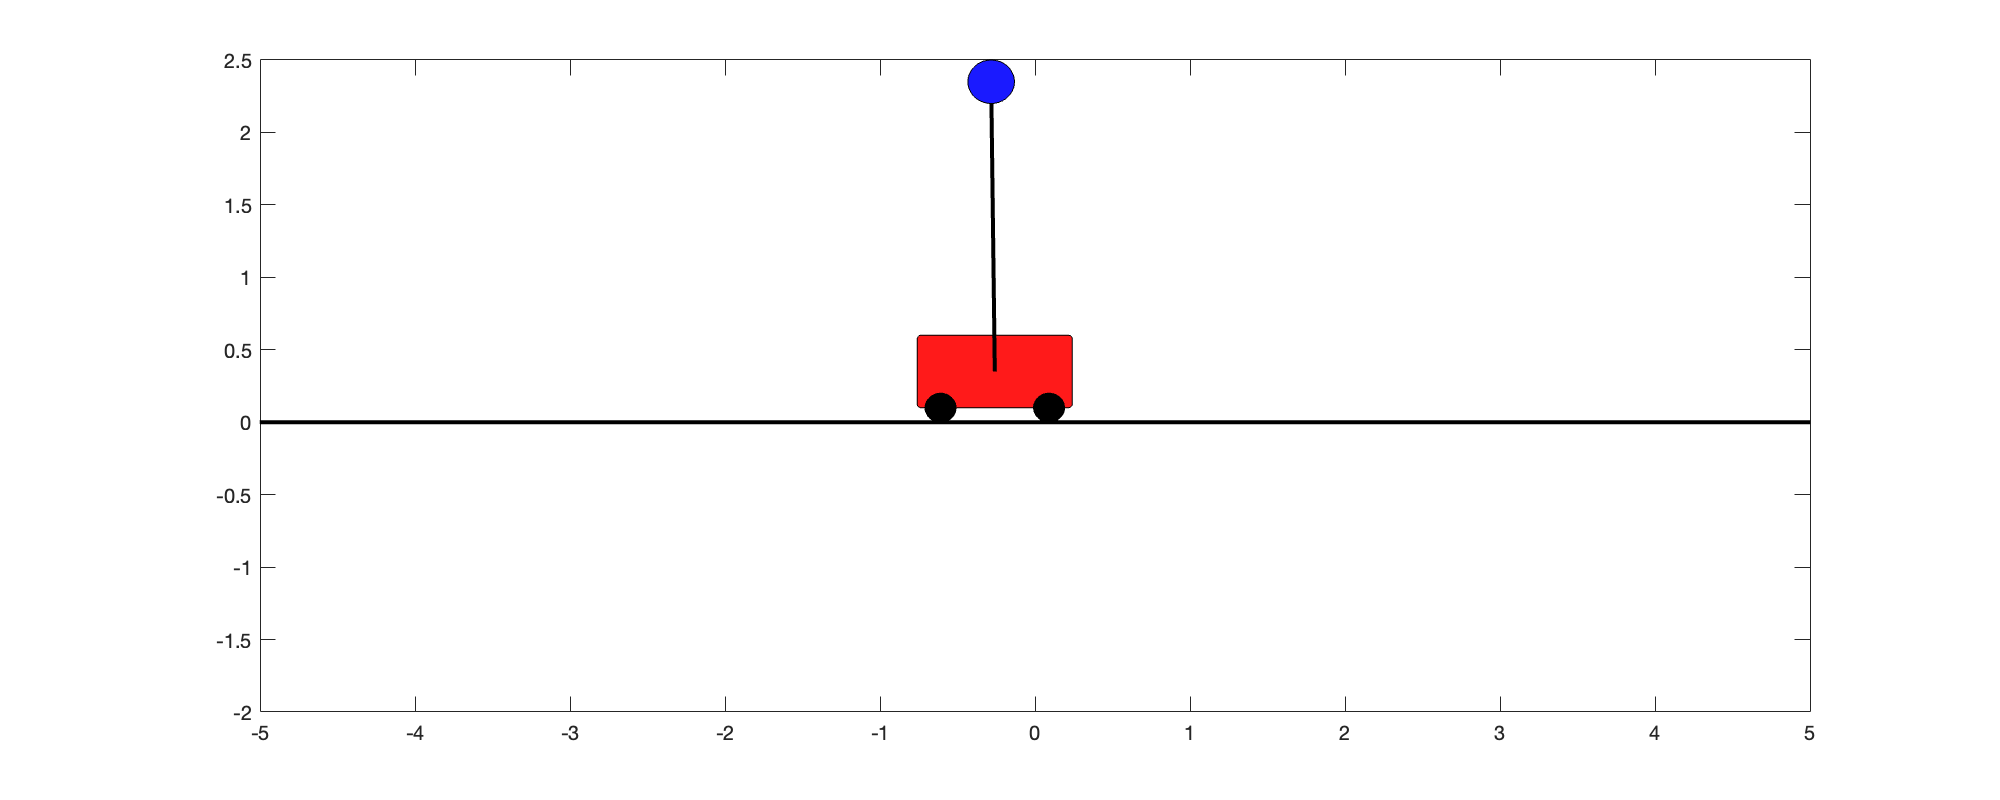

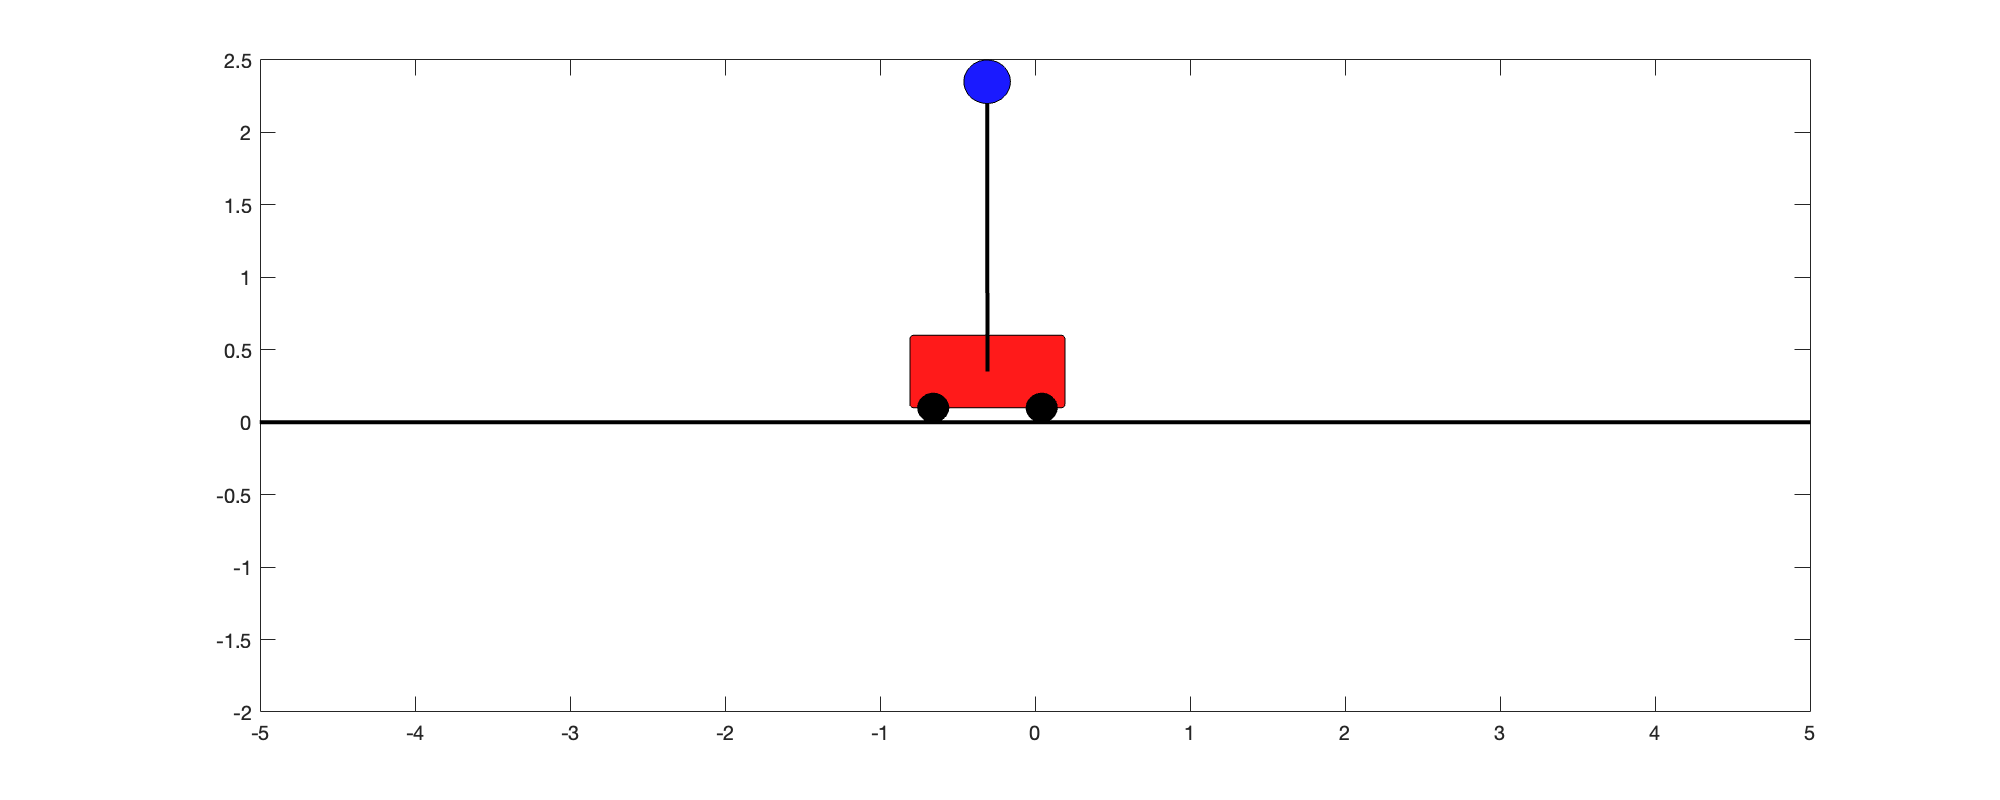

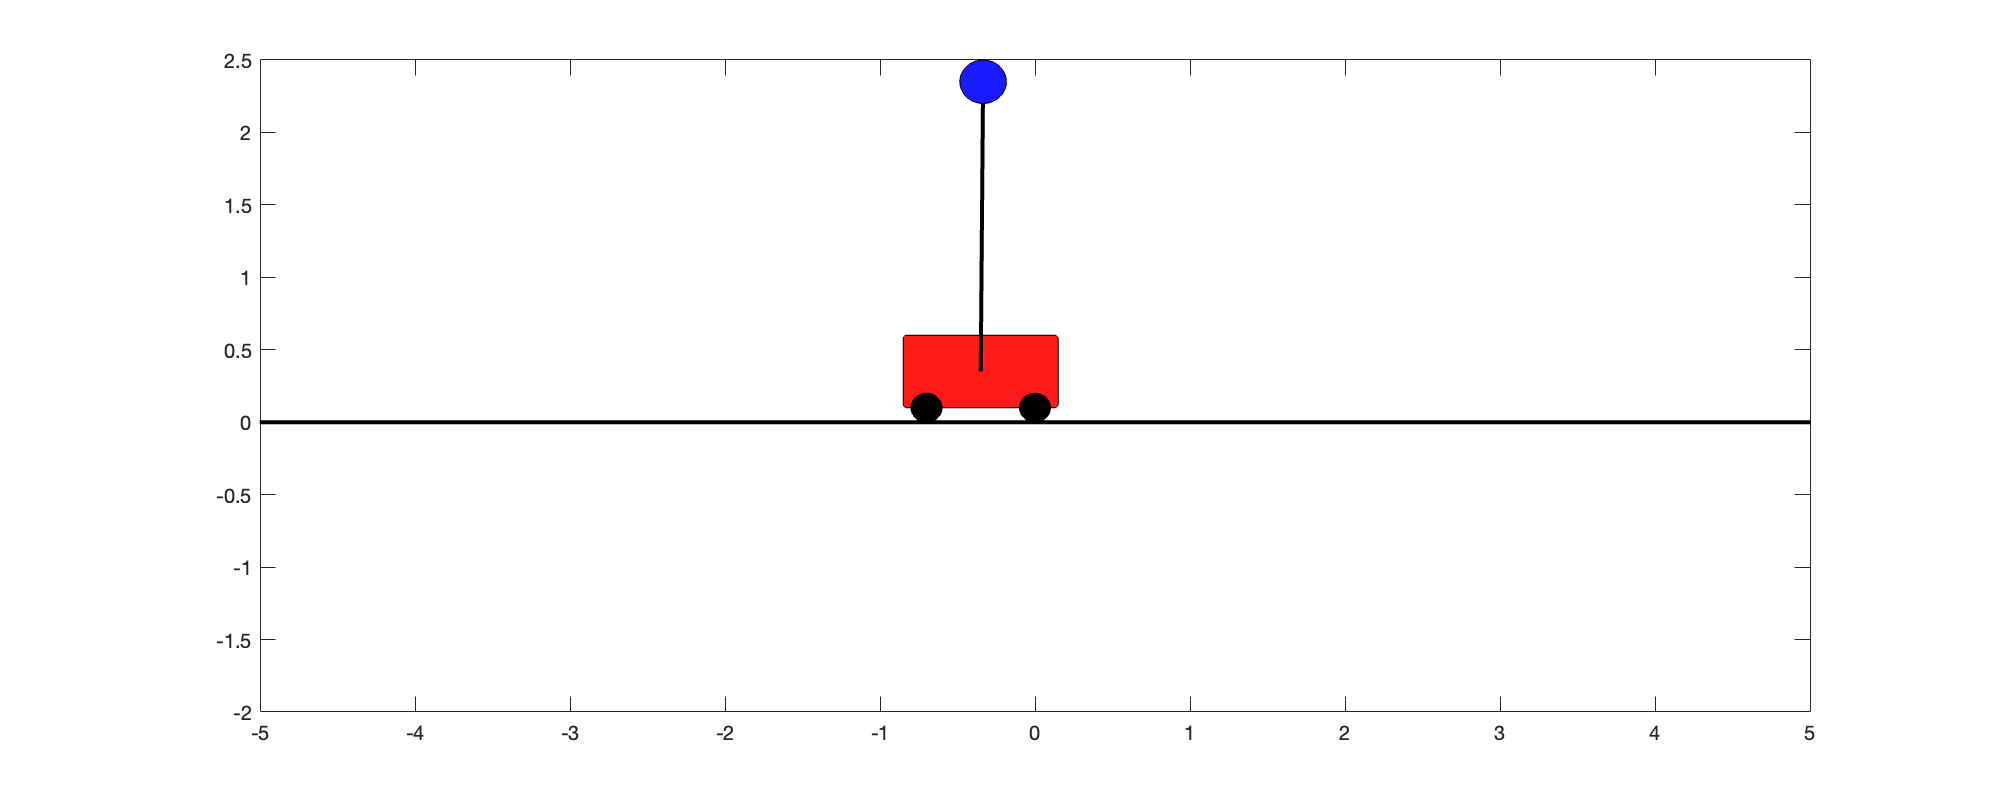


%%
K = lqr(A,B,Q,R);

tspan = 0:.001:10;
if(s==-1)
    y0 = [0; 0; 0; 0];
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K*(y-[4; 0; 0; 0])),tspan,y0);
elseif(s==1)
    y0 = [0; 0; pi+.1; 0];
    %[t,y] = ode45(@(t,y)((A-B*K)*(y-[0; 0; pi; 0])),tspan,y0);
    [t,y] = ode45(@(t,y)cartpend(y,m,M,L,g,d,-K*(y-[0; 0; pi; 0])),tspan,y0);
else
    
end

% obj = VideoWriter('Inverted Pendulum', "MPEG-4")
% obj.Quality = 100;
% obj.FrameRate = 20;
% open(obj)

%figure();
for k=1:100:length(tspan)
    figure();
    drawcartpend(y(k,:),m,M,L);
    print(['Frame ' num2str(k)], '-dpng', '-r150');
end

%writeAnimation(fig,'loop.gif','LoopCount',1)
% myWriter = VideoWriter('Inverted Pendulum', "MPEG-4")
% open(myWriter)
% writeVideo(myWriter, f);
% close(myWriter)
delay = 0.05;

for kk = 1:100:length(tspan)
    
%   Reads our generated PNGs previously
    [A, ~] = imread(['Frame ' num2str(kk) '.png']);
    
%   Stores image data in X and color scale in map after convert from
%   RGB to indexed image
%   Obs.: GIFs only accepts 8 bit images
    [X, map] = rgb2ind(A, 256);
    
%   Starts to construct GIF file frame by frame
%   imwrite receives image data, color scale, file name, delay between frames
%   and constructs a the GIF
%   LoopCount inf causes the animation to continuously loop
    if kk == 1
        imwrite(X, map, "greenarrowicon.gif", 'gif', 'LoopCount', inf, 'DelayTime', delay)
    else
%   WriteMode append causes to add a single frame to an existing file
        imwrite(X, map, "greenarrowicon.gif", 'gif', 'WriteMode', 'append', 'DelayTime', delay)
    end
end

Error using imread>get_full_filename (line 570)
File "Frame 2.png" does not exist.

Error in imread (line 377)
    fullname = get_full_filename(filename);


% Prints a message telling us the GIF is concluded!
disp('End!')

End!


%Nonlinear Euqaiton for cart on a pendulum

function dy = cartpend(y,m,M,L,g,d,u)
Sy = sin(y(3));
Cy = cos(y(3));
D = m*L*L*(M+m*(1-Cy^2));

dy(1,1) = y(2);
dy(2,1) = (1/D)*(-m^2*L^2*g*Cy*Sy + m*L^2*(m*L*y(4)^2*Sy - d*y(2))) + m*L*L*(1/D)*u;
dy(3,1) = y(4);
dy(4,1) = (1/D)*((m+M)*m*g*L*Sy - m*L*Cy*(m*L*y(4)^2*Sy - d*y(2))) - m*L*Cy*(1/D)*u +.01*randn;
end

function drawcartpend(y,m,M,L)
x = y(1);
th = y(3);

% kinematics
% x = 3;        % cart position
% th = 3*pi/2;   % pendulum angle

% dimensions
% L = 2;  % pendulum length
W = 1*sqrt(M/5);  % cart width
H = .5*sqrt(M/5); % cart height
wr = .2; % wheel radius
mr = .3*sqrt(m); % mass radius

% positions
% y = wr/2; % cart vertical position
y = wr/2+H/2; % cart vertical position
w1x = x-.9*W/2;
w1y = 0;
w2x = x+.9*W/2-wr;
w2y = 0;

px = x + L*sin(th);
py = y - L*cos(th);

plot([-10 10],[0 0],'k','LineWidth',2)
hold on
rectangle('Position',[x-W/2,y-H/2,W,H],'Curvature',.1,'FaceColor',[1 0.1 0.1])
rectangle('Position',[w1x,w1y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])
rectangle('Position',[w2x,w2y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])

plot([x px],[y py],'k','LineWidth',2)

rectangle('Position',[px-mr/2,py-mr/2,mr,mr],'Curvature',1,'FaceColor',[.1 0.1 1])

% set(gca,'YTick',[])
% set(gca,'XTick',[])
xlim([-5 5]);
ylim([-2 2.5]);
set(gcf,'Position',[100 550 1000 400])
% box off

%Draw Now- Draws flipbook
drawnow
%
%pause(0.2)

hold off
end